%MENUMNPVI  Menu de Métodos Numéricos para um PVI
%   y = MenuMNPVI(f,a,b,n,y0)
%   y'= f(t,y) com t=[a, b] e y(a)=y0 condição inicial  
%
%INPUT:
%   f - função do 2.º membro da Equação Diferencial
%   [a, b] - extremos do intervalo da variável independente t
%   n - número de subintervalos ou iterações do método
%   y0 - condição inicial t=a -> y=y0
%OUTPUT: 
%   y - vector das soluções aproximações
%
%   12/03/2020 - ArménioCorreia .: armenioc@isec.pt 
%   18/04/2022 -Henrique Marques/João Salgado/Guilherme Camacho

syms y(t)
while 1
    strF = "2*y +3*t"
    f =@(t,y) eval(vectorize(strF));
    try
        fTeste = f(t,y);
        break
    catch ME
        waitfor(errordlg("Introduza uma função em t e y","Erro")) 
    end
end

strF = "2*y +3*t"

while 1
    a = 1
    if (isscalar(a) && isreal(a)) 
        break
    end
end

a = 1


while 1
    b = 3
    if (isscalar(b) && isreal(b) && b>a) 
        break
    end
end

b = 3

while 1
   n = 10
  if(isscalar(n) && isreal(n) && n>=2)
    break
  end
end

n = 10

------- MÉTODOS NUMÉRICOS PARA PVI ------


1. MÉTODO DE EULER 


2. MÉTODO DE EULER MELHORADO 


3. MÉTODO DE RK2


4. MÉTODO DE RK4


5. MÉTODO DE ODE45 


6. MÉTODO DO PONTO MÉDIO 


7. APLICAR OS 6 MÉTODOS EM SIMULTÂNIO 


8. TERMINAR



$$sExata = \frac{15\,{\mathrm{e}}^{2\,t}\,{\mathrm{e}}^{-2}}{4}-\frac{3\,t}{2}-\frac{3}{4}$$

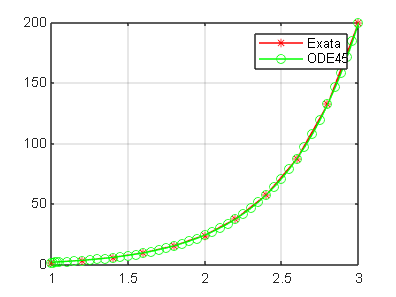

------- MÉTODOS NUMÉRICOS PARA PVI ------


1. MÉTODO DE EULER 


2. MÉTODO DE EULER MELHORADO 


3. MÉTODO DE RK2


4. MÉTODO DE RK4


5. MÉTODO DE ODE45 


6. MÉTODO DO PONTO MÉDIO 


7. APLICAR OS 6 MÉTODOS EM SIMULTÂNIO 


8. TERMINAR



while 1
  y0 = 1.5;
  if (isscalar(b) && isreal(b))
      break
  end
end

primeiraVez=0;
opcao=1;
while opcao ~= 8 
    clc
    disp('------- MÉTODOS NUMÉRICOS PARA PVI ------')
    disp(' ')
    if(~primeiraVez)
        fprintf('1. MÉTODO DE EULER \n')     
        fprintf('2. MÉTODO DE EULER MELHORADO \n')         
        fprintf('3. MÉTODO DE RK2\n')
        fprintf('4. MÉTODO DE RK4\n')
        fprintf('5. MÉTODO DE ODE45 \n')
        fprintf('6. MÉTODO DO PONTO MÉDIO \n')
        fprintf('7. APLICAR OS 6 MÉTODOS EM SIMULTÂNIO \n')
        fprintf('8. TERMINAR\n\n')
        opcao=input('Opção: ');
    else
        opcao=1;
        primeiraVez=0;
    end
    
    switch opcao
        case 1
              yEuler = Neuler(f,a,b,n,y0);
              sExataGeral = dsolve(diff(y,t)==f(t,y))
              sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)
              g = @(t) eval(vectorize(char(sExata)));
              h = (b-a)/n;
              t = a:h:b;
              yExata = g(t);
              erroEuler = abs(yExata-yEuler);
              tabela = [t.',yExata.',yEuler.',erroEuler.']
              array2table(tabela,"VariableNames",{'t','Exata','Euler','erroEuler'})
              plot(t,yExata,"-r*")
              hold on
              plot(t,yEuler,"-go")
              hold off
              grid on
              legend('Exata','Euler')
        case 2  
            f =@(t,y) eval(vectorize(strF));
            yEulerM = MEuler(f,a,b,n,y0);
            sExataGeral = dsolve(diff(y,t)==f(t,y))
            sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)
            g = @(t) eval(vectorize(char(sExata)));
            h = (b-a)/n;
            t = a:h:b;
            yExata = g(t);
            erroEulerM = abs(yExata-yEulerM);
            tabela = [t.',yExata.',yEulerM.',erroEulerM.'];
            array2table(tabela,"VariableNames",{'t','Exata','EulerM','erroEulerM'});

              plot(t,yExata,"-r*")
              hold on
              plot(t,yEulerM,"-bo")
              hold off
              grid on
              legend('Exata','EulerM')
        case 3  
              yRK2 = NRK2(f,a,b,n,y0);   
              sExataGeral = dsolve(diff(y,t)==f(t,y))
              sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)
              g = @(t) eval(vectorize(char(sExata)));
              h = (b-a)/n;
              t = a:h:b;
              yExata = g(t);
              erroRK2 = abs(yExata-yRK2);
              tabela = [t.',yExata.',yRK2.',erroRK2.']
              array2table(tabela,"VariableNames",{'t','Exata','RK2','erroRK2'})
               plot(t,yExata,"-r*")
              hold on
              plot(t,yRK2,"-mo")
              hold off
              grid on
              legend('Exata','RK2')
        case 4
              yRK4 = NRK4(f,a,b,n,y0);   
              sExataGeral = dsolve(diff(y,t)==f(t,y))
              sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)
              g = @(t) eval(vectorize(char(sExata)));
              h = (b-a)/n;
              t = a:h:b;
              yExata = g(t);
              erroRK4 = abs(yExata-yRK4);
              tabela = [t.',yExata.',yRK4.',erroRK4.']
              array2table(tabela,"VariableNames",{'t','Exata','RK4','erroRK4'})
               plot(t,yExata,"-r*")
              hold on
              plot(t,yRK4,"-go")
              hold off
              grid on
              legend('Exata','RK4')         
        case 5
             sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)
             g = @(t) eval(vectorize(char(sExata)));
             h = (b-a)/n;
             t = a:h:b;
             yExata = g(t);
             plot(t,yExata,"-r*")
             hold on
             [t,y] = ode45(f,[a b],y0);
             plot(t,y,"-go")
             hold off
             grid on
             legend('Exata','ODE45')
        case 6
         f =@(t,y) eval(vectorize(strF));
            yPM = AB2(f,a,b,n,y0);
            sExataGeral = dsolve(diff(y,t)==f(t,y))
            sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)
            g = @(t) eval(vectorize(char(sExata)));
            h = (b-a)/n;
            t = a:h:b;
            yExata = g(t);
            erroPM = abs(yExata-yPM);
            tabela = [t.',yExata.',yPM.',erroPM.'];
            array2table(tabela,"VariableNames",{'t','Exata','PontoMedia','erroPontoMedio'})
             plot(t,yExata,"-r*")
              hold on
              plot(t,yPM,"-bo")
              hold off
              grid on
              legend('Exata','Ponto Médio')
        case 7
yEuler = Neuler(f,a,b,n,y0);
yPM = PontoMedio(f,a,b,n,y0);
yEulerM = MEuler(f,a,b,n,y0);
yRK2 = NRK2(f,a,b,n,y0);
yRK4 = NRK4(f,a,b,n,y0);
sExataGeral = dsolve(diff(y,t)==f(t,y))
sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)


g = @(t) eval(vectorize(char(sExata)));

h = (b-a)/n;
t = a:h:b;


yExata = g(t);
erroEuler = abs(yExata-yEuler);
erroEulerM = abs(yExata-yEulerM);
erroRK2 = abs(yExata-yRK2);
erroRK4 = abs(yExata-yRK4);
erroPM = abs(yExata-yPM);

tabela = [t.',yExata.',yEuler.',yEulerM.',yRK2.',yRK4.',yPM.',erroEuler.',erroEulerM.',erroRK2.',erroRK4.',erroPM.'];
array2table(tabela,"VariableNames",{'t','Exata','Euler','EulerM','RK2','RK4','PontoMédio','erroEuler','erroEulerM','erroRK2','erroRK4','erroPM'})


plot(t,yExata,"-r*")
hold on
plot(t,yEuler,"-go")
plot(t,yEulerM,"-y*")
plot(t,yRK2,"-bo")
plot(t,yRK4,"-kd")
plot(t,yPM,"-wo")
[t,y] = ode45(f,[a b],y0);
plot(t,y,"-ms")


hold off
grid on
legend('Exata','Euler','EulerM','RK2','RK4','PontoMédio','ODE45')

    end 
     if opcao ~=8
       tecla =input('\nPrima uma tecla para continuar ...');
    end
end